# Ejemplo Aliasing

Generacion de señal de tiempo continuo

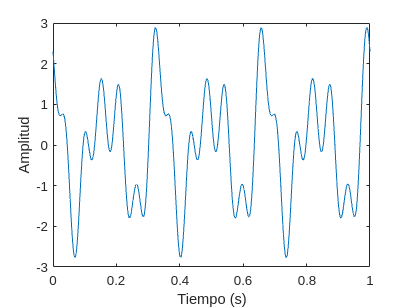

t = 0:0.0001:1;
xt = 1.5*cos(2*pi*6*t) + 0.8*cos(2*pi*9*t) -0.9*sin(2*pi*18*t);
figure()
plot(t,xt)
xlabel('Tiempo (s)')
ylabel('Amplitud')

Muestreo de la señal de tiemp continuo

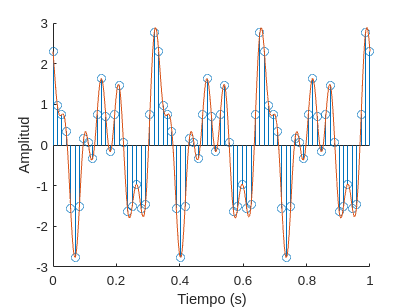

Fs = 72;
Ts = 1/Fs;
nT = 0:Ts:1;
xnT = 1.5*cos(2*pi*6*nT) + 0.8*cos(2*pi*9*nT) -0.9*sin(2*pi*18*nT);
figure()
hold on
stem(nT,xnT)
plot(t,xt)
xlabel('Tiempo (s)')
ylabel('Amplitud')
hold off

Reconstruccion de la señal de tiempo continuo a partir de las muestras

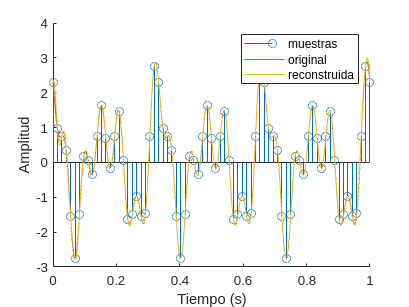

xtrc = sinc_interp(xnT,nT,t);
figure()
hold on
stem(nT,xnT)
plot(t,xt)
plot(t,xtrc)
xlabel('Tiempo (s)')
ylabel('Amplitud')
legend('muestras','original','reconstruida')
hold off

¿Como comparar las señales y obtener una medida de la calidad de la reconstruccion?

% Su codigo
